clear all
close all
clc

## Loading In Audio

handel = load("handel.mat");
laughter = load("laughter.mat");
orighandel = handel.y;
origlaughter = laughter.y;
origsample = handel.Fs;
handel.y = handel.y(linspace(1,handel.Fs*5,handel.Fs*5));
laughter.y = laughter.y(linspace(1,laughter.Fs*5,laughter.Fs*5));

## Creating our 2kHz lowpass filter and applying it

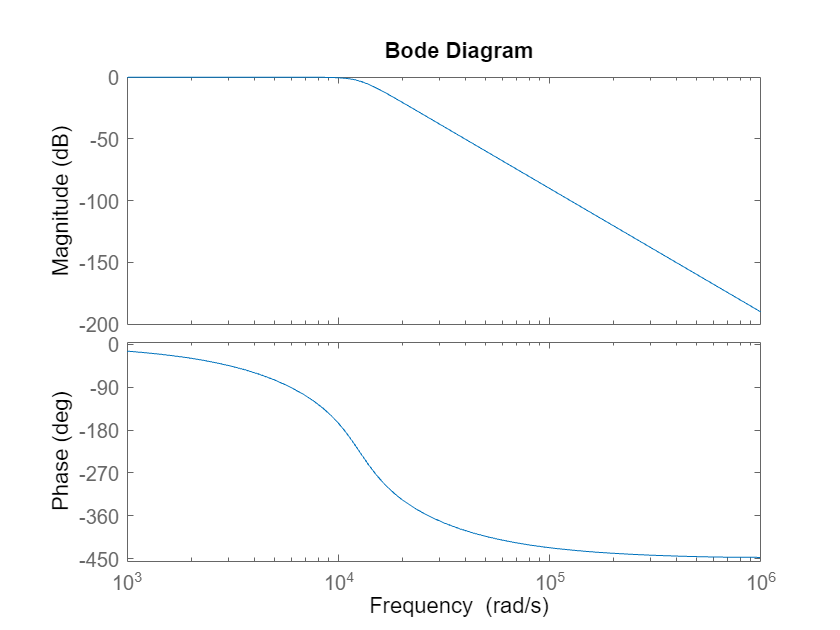

fc = 2000; % Hz Cutoff Frequency
[num, den] = butter(5,2*pi*fc,"low",'s'); % Generating butter filter coefficients
H_butter = tf(num,den); % generating our transfer function
timevec = linspace(0,5,40960); % creating a 5 second time vector
handel.y = lsim(H_butter,transpose(handel.y),timevec); % Filtering our handel audio sample
laughter.y = lsim(H_butter,transpose(laughter.y),timevec); % Filtering our laughter audio sample
bodeplot(H_butter) % Plotting the bode of our low pass transfer function

## Normalizing the signals to [0,2] and upsampling to 120 kHz

samp_rate = 120000; % Finding our sample rate
target_samples = samp_rate*5; % Setting a total number of sampples
handel.y = resample((1.+(handel.y./(max(abs(handel.y))))),target_samples,length(handel.y)); % resample handel to 120000 samples
laughter.y = resample((1.+(laughter.y./(max(abs(laughter.y))))),target_samples,length(laughter.y)); % resample laughter to 120000 samples
handel.Fs = samp_rate; % setting the new sample rates
laughter.Fs = samp_rate; % setting the new sample rates

## Carrier Signals

tlength = linspace(0,5,target_samples); % Setting a 5 second time vector for generating carrier signals
ThirtyKHz= transpose(cos(30000*2*pi*tlength));% 30 KHz
TwentyKHz = transpose(cos(20000*2*pi*tlength));% 20 KHz
TwentyoneKHz = transpose(cos(20000*2*pi*tlength));% 21 KHz

## Multiplying The Signals

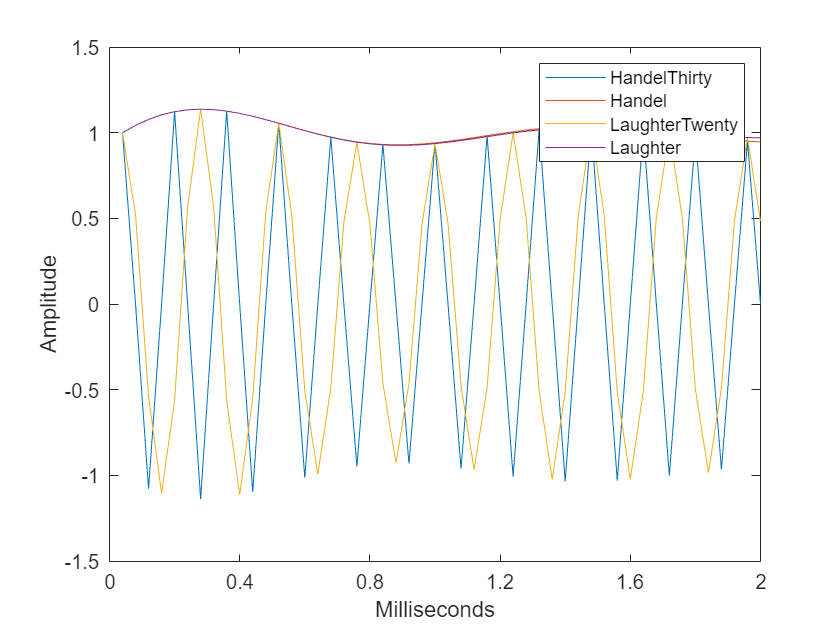

handelthirty = handel.y.*ThirtyKHz; % Modulating the handel sample with the thirty khz
laughtertwenty = laughter.y.*TwentyKHz; % Modulating the laughter sample with the twenty khz
handeltwentyone = handel.y.*TwentyoneKHz; % Modulating the handel sample with the twenty-one khz
SignalSum = handelthirty+laughtertwenty; % Adding these two together
SignalSum2021 = handeltwentyone+laughtertwenty; % Signal Sum for additional question
% Plotting our signals
plot(handelthirty)
hold on
plot(handel.y)
hold on
plot(laughtertwenty)
hold on
plot(laughter.y)
hold on
xlim([0,50]);
legend('HandelThirty','Handel','LaughterTwenty','Laughter');
xticklabels({0,.4,.8,1.2,1.6,2})
xlabel('Milliseconds')
ylabel('Amplitude')
hold off

## Examining With MyFFT

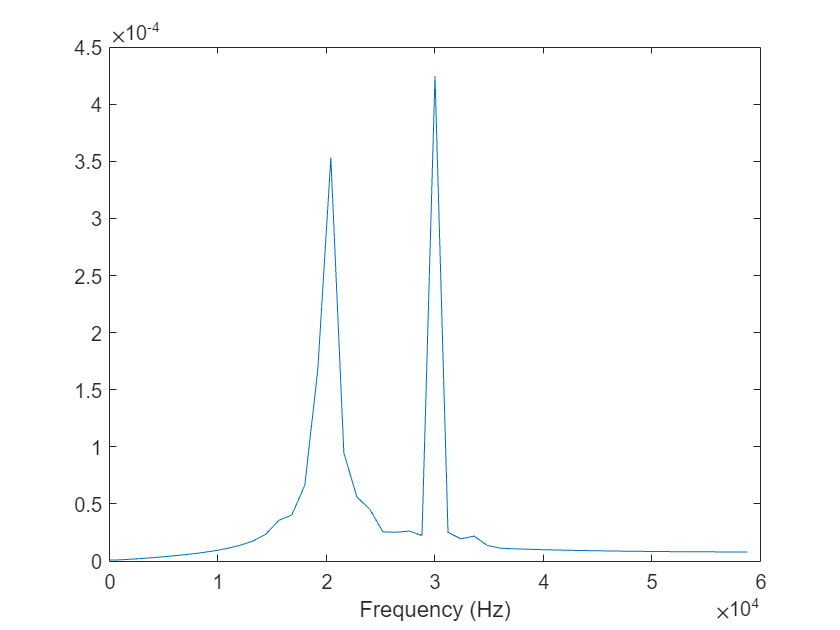

myFFT(SignalSum,120000,100)

## Demodulation

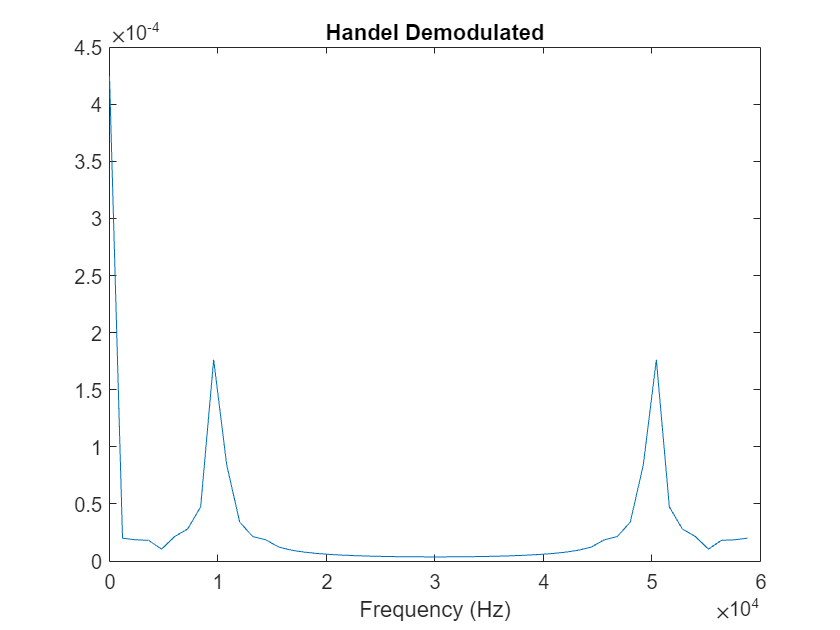

DemoddedHandel = SignalSum .* ThirtyKHz; % Demodulate Handel 
DemoddedLaughter = SignalSum .* TwentyKHz; % Demodulate Laughter
myFFT(DemoddedHandel,120000,100) 
title("Handel Demodulated")
hold off

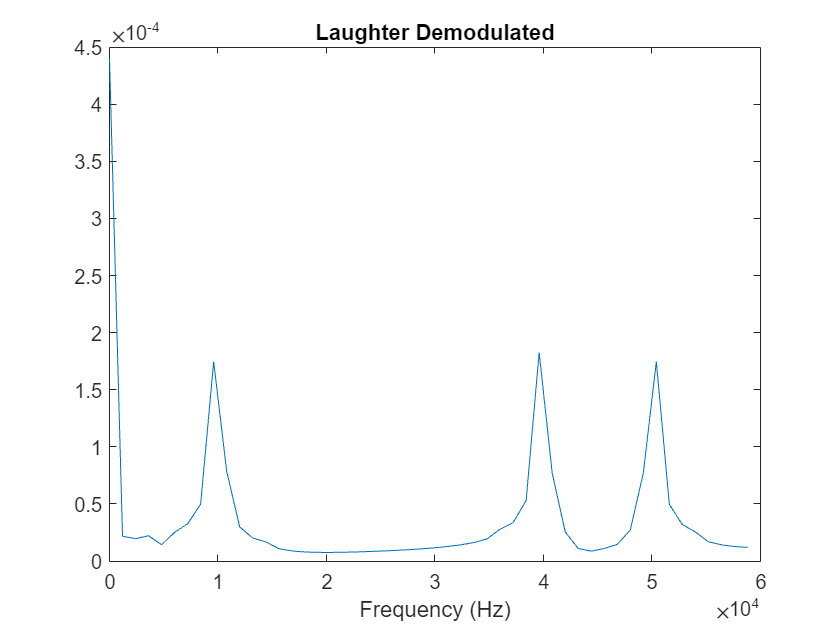

myFFT(DemoddedLaughter,120000,100)
title("Laughter Demodulated")

## Filtering Signals

[num,den] = butter(5,2*pi*1200,"low","s"); % Generating coefficients for our filter
mylow = tf(num,den); % Lowpass filter
FDHandel = lsim(mylow,DemoddedHandel,tlength); % Generating our filtered handel
FDLaughter = lsim(mylow,DemoddedLaughter,tlength); % Generating our filtered laughter

## Plot the fourier transforms of our filtered demodulated signals

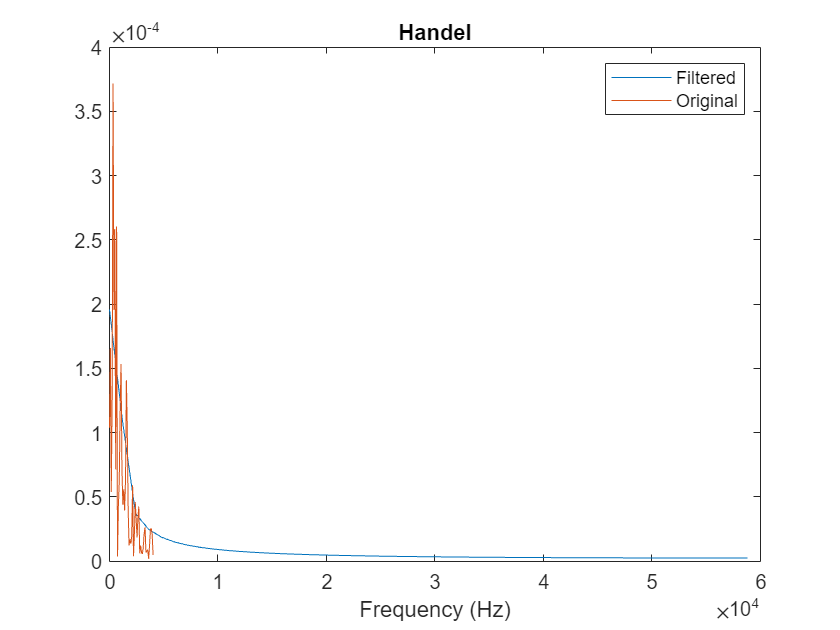

myFFT(FDHandel,120000,100)
title("Handel")
hold on
myFFT(orighandel,origsample,100)
legend("Filtered","Original");
hold off

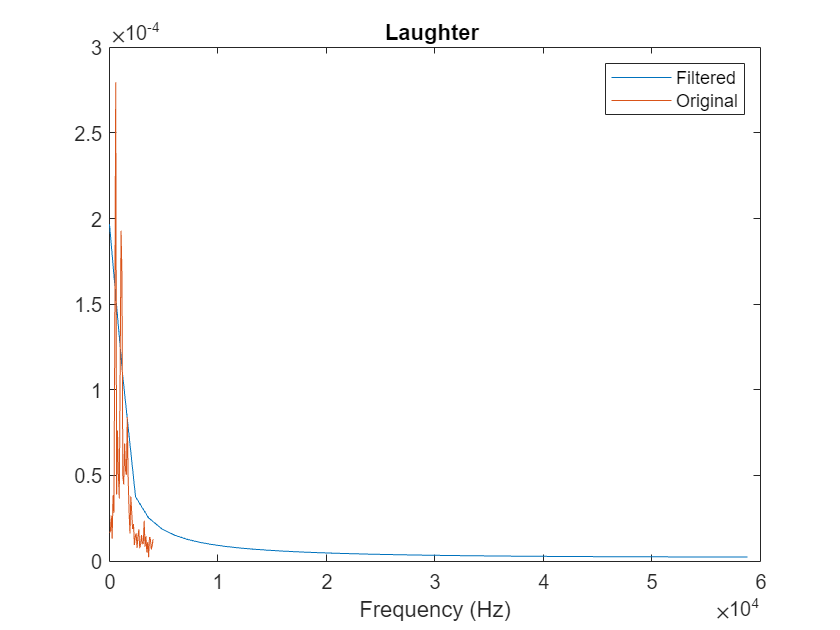

myFFT(FDLaughter,120000,100)
title("Laughter ")
hold on 
myFFT(origlaughter,origsample,100)
legend("Filtered","Original");
hold off

## Play our filtered demodulated signals

soundsc(FDHandel,120000);
pause(5);
soundsc(FDLaughter,120000);
pause(5)

## Twenty and Twenty one

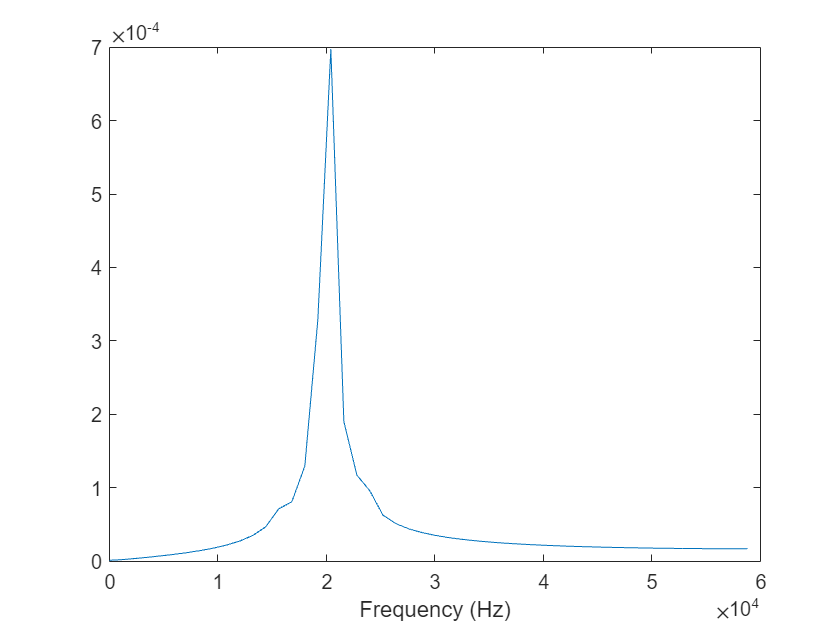

myFFT(SignalSum2021,120000,100) % Examining the frequencies

DemoddedLaughter20 = SignalSum2021 .* TwentyKHz; % Filtering out our laughter
DemoddedHandel21 = SignalSum2021 .* TwentyoneKHz; % Filter out our handel
FDHandel21 = lsim(mylow,DemoddedHandel21,tlength); % Generating our filtered handel
FDLaughter20 = lsim(mylow,DemoddedLaughter20,tlength); % Generating our filtered laughter

## Plot the fourier transforms of our filtered demodulated signals

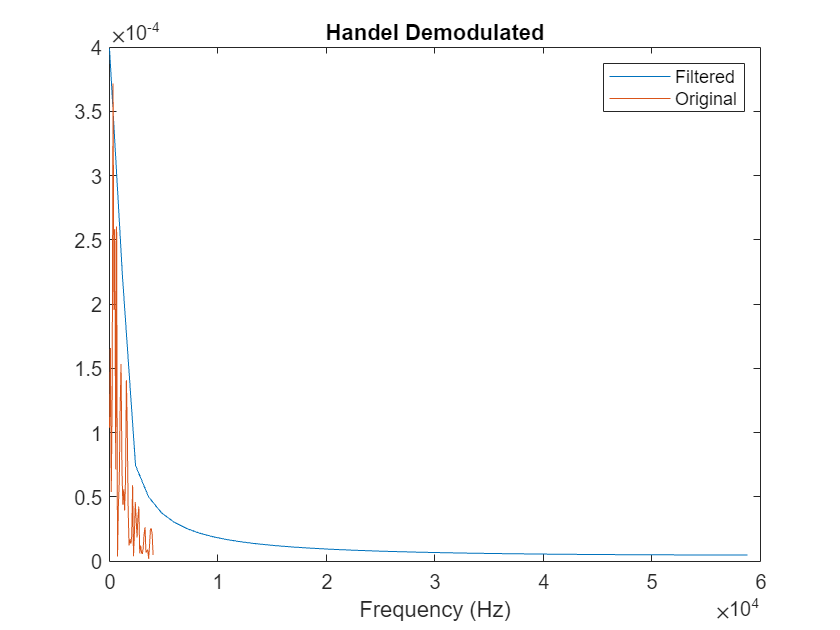

myFFT(FDHandel21,120000,100)
title("Handel Demodulated")
hold on
myFFT(orighandel,origsample,100)
legend("Filtered","Original");
hold off

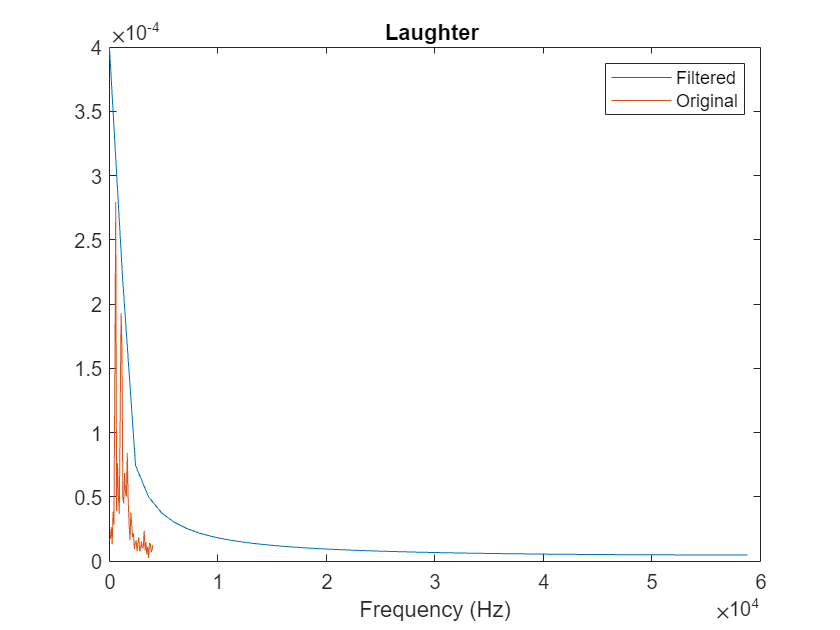

myFFT(FDLaughter20,120000,100)
title("Laughter ")
hold on 
myFFT(origlaughter,origsample,100)
legend("Filtered","Original");
hold off

## Play our filtered demodulated signals

soundsc(FDHandel21,120000); % Handel
pause(5)
soundsc(FDLaughter20,120000); % Laughter
pause(5)